close all;clear;clc

x = linspace(0,1,20);
t = linspace(0,0.2,5);
m = 0;


X=[0.2 0.3 0.4 0.5;0.2 0.3 0.4 0.5]';
global par;
for i=1:length(X)
    disp(['the iteration number is : ',num2str(i)])
    par = X(i,:) ; % sample parameter space
    y1 = pdepe(m,@pdefun_v1,@pdeic,@pdebc,x,t);
    y(:,:,:,i)=y1;
end
%%

%global par1 par2;


par=[0.2 0.2];
sol_2 = pdepe(m,@(x,t,u,dudx)pdefun_v1(x,t,u,dudx,par),@pdeic,@pdebc,x,t);
u1_2=sol_2(:,:,1);
u2_2=sol_2(:,:,2);
u3_2=sol_2(:,:,3);

plot(x, u1_2(:,:),'--');
plot(x, u2_2(:,:),'--');
plot(x, u3_2(:,:),'--');



sol = pdepe(m,@pdefun,@pdeic,@pdebc,x,t);
options=[];
sol_2 = pdepe(m,@pdefun_v1,@pdeic,@pdebc,x,t);
u1_2=sol_2(:,:,1);
u2_2=sol_2(:,:,2);
u3_2=sol_2(:,:,3);

plot(x, u1_2(:,:),'--');
plot(x, u2_2(:,:),'--');
plot(x, u3_2(:,:),'--');

u1 = sol(:,:,1);
u2 = sol(:,:,2);
u3 = sol(:,:,3);
plot(x, u1(:,:));
title('C_{CO_2}(z,t)')
xlabel('Distance z')
ylabel('Concentration')



surf(x,t,u1)
title('C_{CO_2}(z,t)')
xlabel('Distance z')
ylabel('Time t')

plot(x, u2(:,:));
title('C_{DOC}(z,t)')
xlabel('Distance z')
ylabel('Concentration')

surf(x,t,u2)
title('C_{DOC}(z,t)')
xlabel('Distance z')
ylabel('Time t')

plot(x, u3(:,:));
title('C_{O_2}(z,t)')
xlabel('Distance z')
ylabel('Concentration')

surf(x,t,u3)
title('C_{O_2}(z,t)')
xlabel('Distance z')
ylabel('Time t')

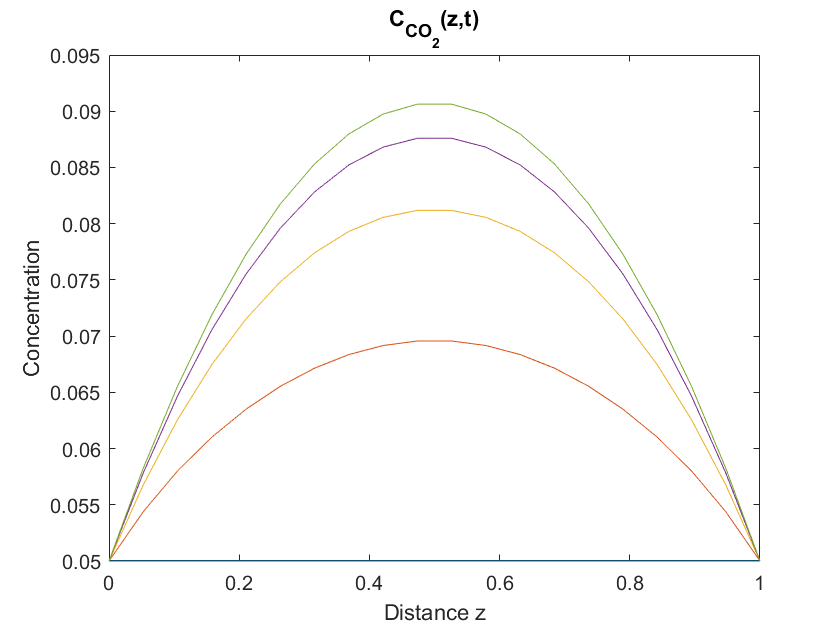

%-----dynamic biomass--------------------
close all;clear;clc
x = linspace(0,1,20);
t = linspace(0,0.2,5);
m = 0;

sol_B = pdepe(m,@pdefunB,@pdeicB,@pdebcB,x,t);
u1 = sol_B(:,:,1);
u2 = sol_B(:,:,2);
u3 = sol_B(:,:,3);
u4 = sol_B(:,:,4);
plot(x, u1(:,:));
title('C_{CO_2}(z,t)')
xlabel('Distance z')
ylabel('Concentration')


plot(x, u1(:,:));
title('C_{CO_2}(z,t)')
xlabel('Distance z')
ylabel('Concentration')

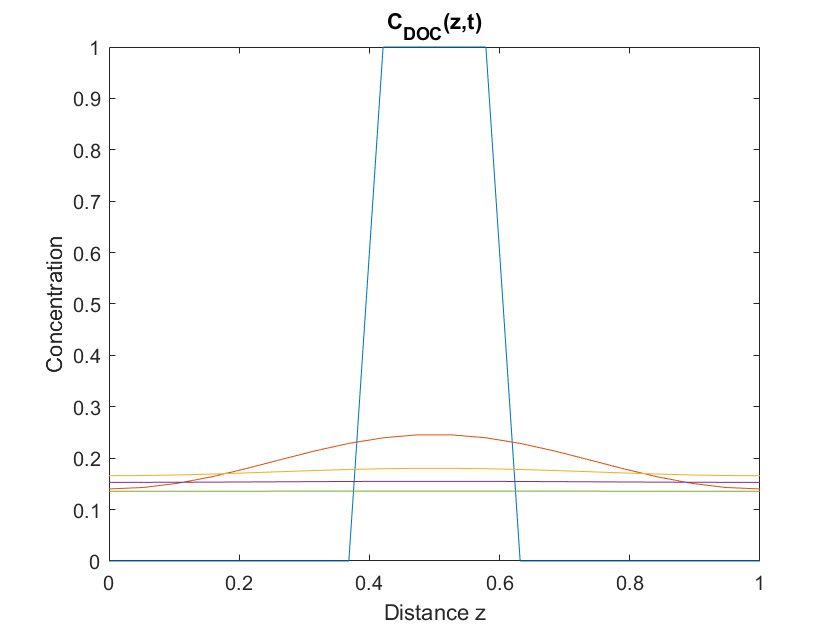


plot(x, u2(:,:));
title('C_{DOC}(z,t)')
xlabel('Distance z')
ylabel('Concentration')

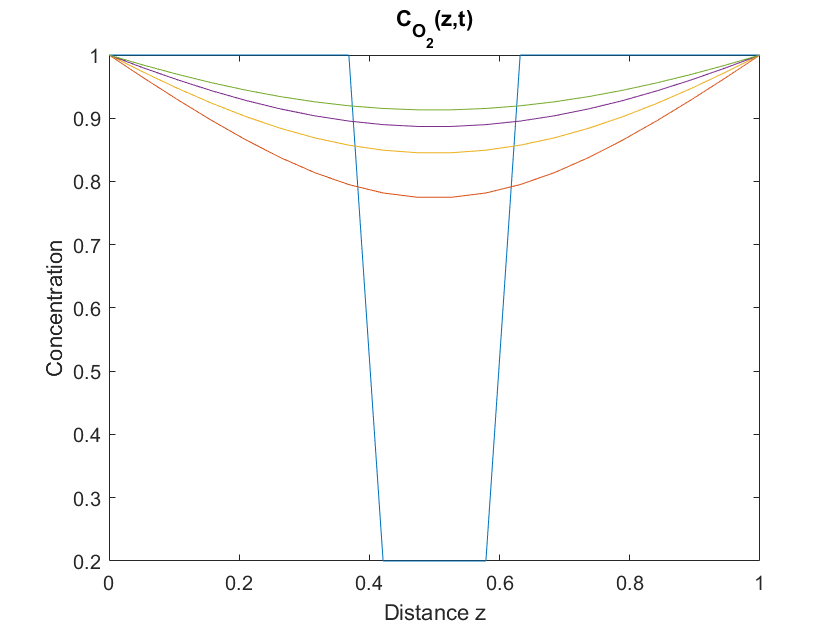



plot(x, u3(:,:));
title('C_{O_2}(z,t)')
xlabel('Distance z')
ylabel('Concentration')

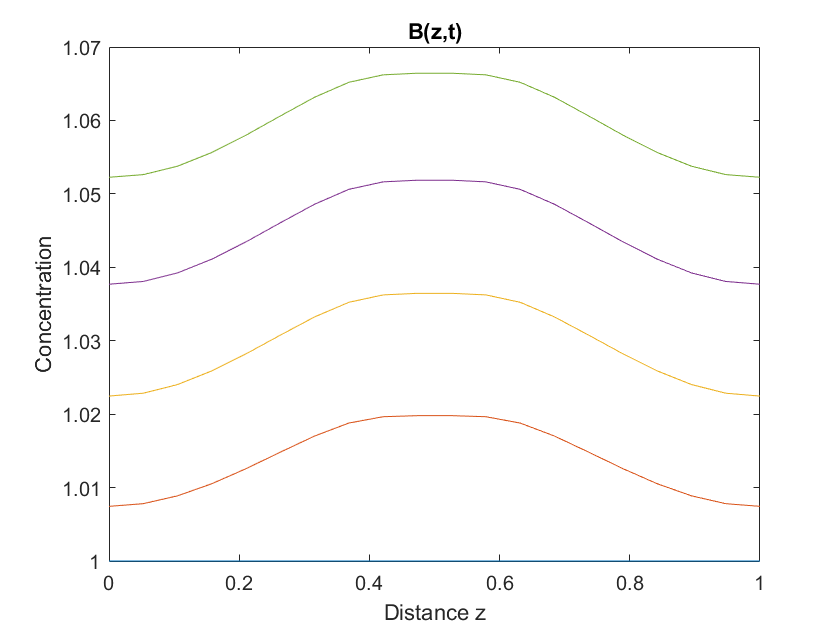


plot(x, u4(:,:));
title('B(z,t)')
xlabel('Distance z')
ylabel('Concentration')

function [c,f,s] = pdefun(x,t,u,dudx) % Equation to solve
c = [1; 1; 1];
f = dudx;
S = u(2)./(0.2+u(2)).*u(3)./(0.2+u(3));
s = [S;-S;-S];
end
% ---------------------------------------------
function u0 = pdeic(x) % Initial Conditions
u0 = [0.05; 0; 1];
if x >= 0.4 && x <= 0.6
  u0(1) = 0.05;
  u0(2) = 1;
  u0(3) = 0.2;
end
end
% ---------------------------------------------
function [pl,ql,pr,qr] = pdebc(xl,ul,xr,ur,t) % Boundary Conditions
pl = [ul(1)-0.05; 0; ul(3)-1];
ql = [0; 1; 0];
pr = [ur(1)-0.05; 0; ur(3)-1];
qr = [0; 1; 0];
end
%---------------------------------------------
% IC function interpolating known points 
function u0 = pdeicv1(x)
xMesh = [0 0.39 0.41 0.59 0.61 1];
icData = [0.05 0.05 0.05 0.05 0.05 0.05; 0, 0, 1, 1, 0, 0; 1, 1, 0.2, 0.2, 1, 1];
u0 = interp1(xMesh,icData',x,'pchip')';
end

function [c,f,s] = pdefun_v1(x,t,u,dudx,par) % Equation to solve
yMesh = [0 0.2 0.3 0.6 0.8 1];
yData = [0.5 0.6 0.7 0.8 0.6 0.5]; 
ku2=par(1);
ku3=par(2);
thetaR = interp1(yMesh,yData,x,'pchip')';
c = [thetaR; thetaR; thetaR];
D = interp1(yMesh,yData,x,'pchip')';
f = [D;D;D].*dudx;
S = u(2)./(ku2+u(2)).*u(3)./(ku3+u(3));
s = [S;-S;-S];
end
%---------------------------------------------
%---------------------------------------------
% pde systems with Biomass
function [c,f,s] = pdefunB(x,t,u,dudx) % Equation to solve
c = [1; 1; 1; 1];
f = [1; 1; 1; 0].*dudx;
S = u(4).*u(2)./(0.2+u(2)).*u(3)./(0.2+u(3));
s = [S;-S;-S;0.8*S];
end
% ---------------------------------------------
function u0 = pdeicB(x) % Initial Conditions
u0 = [0.05; 0; 1; 1];
if x >= 0.4 && x <= 0.6
  u0(1) = 0.05;
  u0(2) = 1;
  u0(3) = 0.2;
end
end
% ---------------------------------------------
function [pl,ql,pr,qr] = pdebcB(xl,ul,xr,ur,t) % Boundary Conditions
pl = [ul(1)-0.05; 0; ul(3)-1; 0];
ql = [0; 1; 0; 1];
pr = [ur(1)-0.05; 0; ur(3)-1; 0];
qr = [0; 1; 0; 1];
end